addpath(genpath('../helperFunctions'))

stimPath = '../stimulusSets/isettreeshrew/treeshrew_10/';
taskType = 'Camel_v2_test_nn';
stimSet = [taskType,'_quad/register_centered/merged/'];

d = natsortfiles(dir('../4_treeShrewBehavior/behaviorData/shrewData.mat'));
load([d(end).folder,'/',d(end).name])

targ_idx = unique(allData.(taskType).T_Expt_ID);
train_targ_val = [0 6 9 13 17 32 38 40 44 55 60 65];
test_targ_val = setdiff(targ_idx,train_targ_val);
[~,train_targ_idx] = ismember(train_targ_val,targ_idx);
train_targ_idx(train_targ_idx==0) = [];
[~,test_targ_idx] = ismember(test_targ_val,targ_idx);

dist_idx = unique(allData.(taskType).D_Expt_ID);
if strcmp(taskType,'Camel_Rhino_test_nn')
    distractor = 'rhino';
    train_dist_val = [0 3 11 16 70 76 92];
else
    distractor = 'wrench';
    train_dist_val = [0 14 26 83 87 92 93];
end
test_dist_val = setdiff(dist_idx,train_dist_val);
[~,train_dist_idx] = ismember(train_dist_val,dist_idx);
train_dist_idx(train_dist_idx==0) = [];
[~,test_dist_idx] = ismember(test_dist_val,dist_idx);

wave = 5:10:75;
orient = 0:15:165;
g = gabor(wave,orient);

allImgs = natsortfiles(dir([stimPath,stimSet]));
allImgs = allImgs(3:end);


dist_data = load(['../stimulusSets/',taskType,'/wrench_trans_data.mat']);
targ_data = load(['../stimulusSets/',taskType,'/camel_trans_data.mat']);

row0 = {'c000',0,0,0,0,0,1};
targ_data.tab = [row0; targ_data.tab; targ_data.tab];
row0 = {'w000',0,0,0,0,0,1};
dist_data.tab = [row0; dist_data.tab; dist_data.tab];

targ_scale = targ_data.tab(targ_idx+1,'Scale');
dist_scale = dist_data.tab(dist_idx+1,'Scale');

[targ_sort, targ_sort_idx] = sort(table2array(targ_scale),'descend');
[dist_sort, dist_sort_idx] = sort(table2array(dist_scale),'ascend');


avgPwr_targ = nan(length(targ_idx),length(wave)*length(orient));
for tt = 1:length(targ_idx)
    img = double(imread(sprintf('%s%s/camel_%d.png',stimPath,stimSet,targ_idx(tt))));
    img = mean(img,3);

    outMag = imgaborfilt(img,g);
    avgPwr_targ(tt,:) = mean(outMag,[1,2]);
    pwr_targ(tt,:) = outMag(:);
end

avgPwr_dist = nan(length(dist_idx),length(wave)*length(orient));
for dd = 1:length(dist_idx)
    img = double(imread(sprintf('%s%s/%s_%d.png',stimPath,stimSet,distractor,dist_idx(dd))));
    img = mean(img,3);

    outMag = imgaborfilt(img,g);
    avgPwr_dist(dd,:) = mean(outMag,[1,2]);
    pwr_dist(dd,:) = outMag(:);
end


alldist = pdist2(avgPwr_targ, avgPwr_dist);
alldiff = targ_scale.Scale - dist_scale.Scale';
corr2(alldiff,alldist)

ans = 0.7112

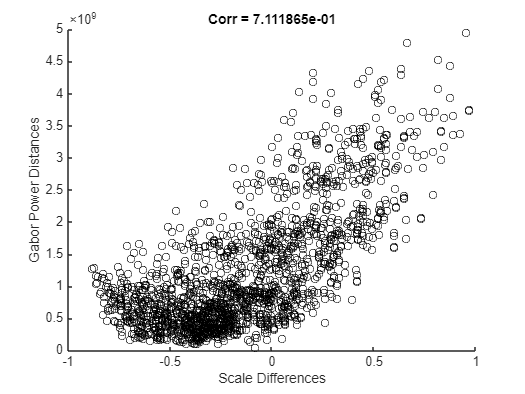

figure()
scatter(alldiff, alldist, 'ko')
xlabel('Scale Differences')
ylabel('Gabor Power Distances')
title(sprintf('Corr = %d', corr2(alldiff, alldist)))

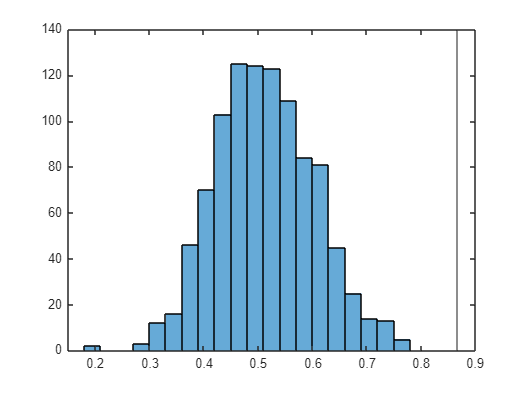

trainPwr_raw = [avgPwr_targ(train_targ_idx,:);avgPwr_dist(train_dist_idx,:)];
testPwr_raw = [avgPwr_targ(test_targ_idx,:);avgPwr_dist(test_dist_idx,:)];

mu = mean(trainPwr_raw);
sd = std(trainPwr_raw);
sd(sd == 0) = 1;

trainX = (trainPwr_raw - mu) ./ sd;
testX  = (testPwr_raw  - mu) ./ sd;

trainY = [zeros(length(train_targ_idx),1); ones(length(train_dist_idx),1)];
testY = [zeros(length(test_targ_idx),1); ones(length(test_dist_idx),1)];

Mdl = fitcsvm(trainX, trainY);
pred_train = predict(Mdl,trainX);
pred = predict(Mdl, testX);
perf = sum((testY-pred)==0)/length(pred);

perf_samp = nan(1,1000);
for i = 1:1000
    y_shuf = trainY(randperm(length(trainY)));
    Mdl_shuf = fitcsvm(trainX, y_shuf);
    pred_shuf = predict(Mdl_shuf, testX);
    perf_samp(i) = sum((testY - pred_shuf) == 0) / length(testY);
end
p_val = mean(perf_samp >= perf);

figure;
histogram(perf_samp)
hold on;
xline(perf)